successful_trials_val = strfind(triggerValues, [100,150,190,223]);
succ_trial_num = length(successful_trials_val);
fprintf ('number of successful trials = %d\n', succ_trial_num);

number of successful trials = 138


% cluster trials
reward_period_sam = triggerTimes(successful_trials_val + 2) - triggerTimes(successful_trials_val + 1) + 1;
reward_period_time = double(reward_period_sam) / fs;
reward_period_time = round(reward_period_time, 1)

reward_period_time =     0.1000    0.1000    0.1000    0.1000    0.2000    0.1000    0.1000    0.2000    0.1000    1.0000    0.1000    0.1000    0.2000    0.1000    0.1000    0.2000    0.1000    0.1000    0.1000    0.1000    0.1000    0.2000    0.2000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    1.0000    0.1000    0.1000    0.2000    0.1000    0.2000    0.1000    0.1000    0.1000    0.1000    0.1000    0.2000    0.1000    0.1000    0.1000    0.1000    1.0000    0.1000    0.1000


event_indices = triggerTimes(successful_trials_val);

epoched_data = epochAndCluster(rawData, [-0.5 4], event_indices, reward_period_time, 10, fs);


% ERP Calculation

ERP = struct( ...
        'ext_reward', mean(epoched_data.ext_reward, 3), ...
        'norm_reward', mean(epoched_data.norm_reward, 3), ...
        'BG_reward', mean(epoched_data.BG_reward, 3)  ...
    );

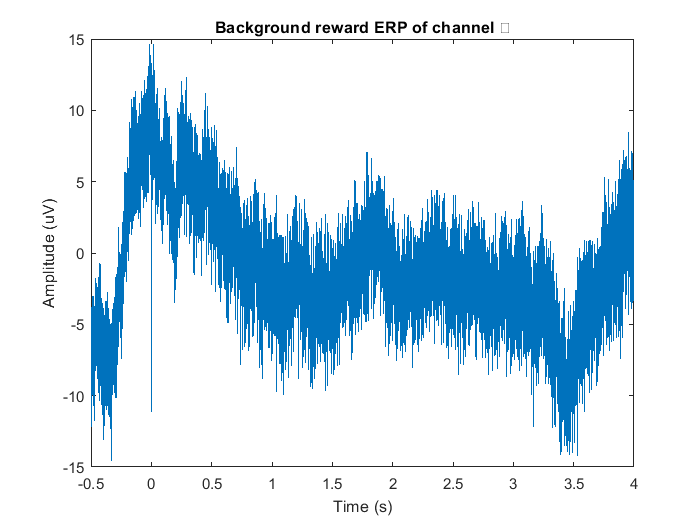

plot_ERP(ERP, 2, "BG", fs);

% figure;
% time = linspace(-500,4000,4.5*fs+1);
% plot(time, ERP.ext_reward(1, :));
% title(['Extended reward ERP of channel ' 1]);

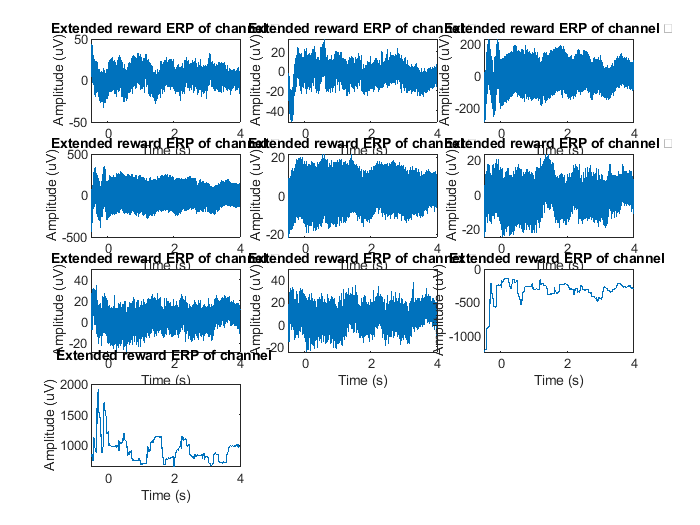

figure;
for i=1:10
   subplot(4,3,i, 'align');
   plot_ERP(ERP, i, "ext", fs);
end

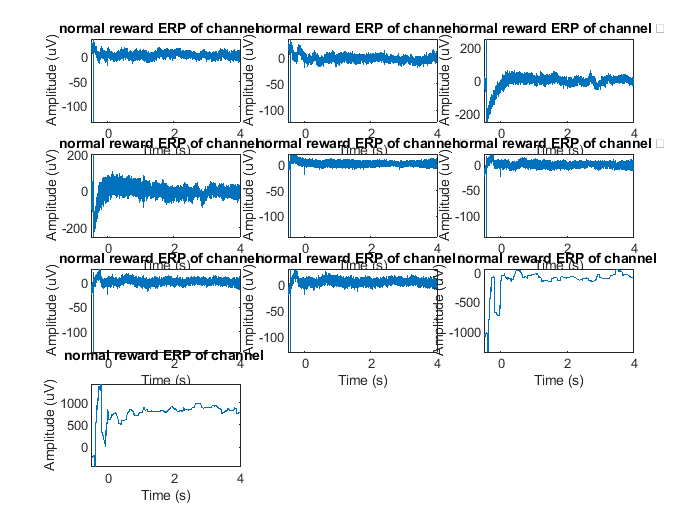

figure;
for i=1:10
   subplot(4,3,i, 'align');
   plot_ERP(ERP, i, "norm", fs);
end

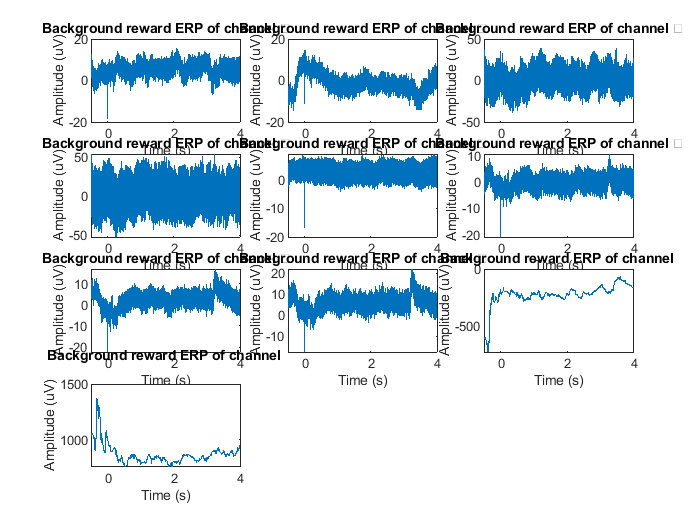

figure;
for i=1:10
   subplot(4,3,i, 'align');
   plot_ERP(ERP, i, "BG", fs);
end

function plot_ERP(ERP, channel_id, rw_type, fs)
    time = linspace(-0.5,4,4.5*fs+1);
    switch rw_type
        case "ext"
            plot(time, ERP.ext_reward(channel_id, :));
            title(['Extended reward ERP of channel ' channel_id]);
        case "norm"
            plot(time, ERP.norm_reward(channel_id, :));
            title(['normal reward ERP of channel ' channel_id]);
        case "BG"
            plot(time, ERP.BG_reward(channel_id, :));
            title(['Background reward ERP of channel ' channel_id]);
    end
    xlabel('Time (s)');
    ylabel('Amplitude (uV)');
end

function epoched_data = epochAndCluster(rawData, epoch_limits, event_indices, reward_period_time, n_chan, fs)

    n_ext_reward = sum(reward_period_time==1);
    n_norm_reward = sum(reward_period_time==0.2);
    n_BG_reward = sum(reward_period_time==0.1);
    
    % Calculate the number of samples per epoch and per baseline
    epoch_samples = round(epoch_limits * fs); % number of samples per epoch
    
    n_epochs = length(event_indices);
    n_points = epoch_samples(2) - epoch_samples(1) + 1;     % number of points per epoch
    
    epoched_data = struct( ...
            'ext_reward', zeros(n_chan, n_points, n_ext_reward), ...
            'norm_reward', zeros(n_chan, n_points, n_norm_reward), ...
            'BG_reward', zeros(n_chan, n_points, n_BG_reward)  ...
        );
    
    epoched_data.ext_reward = zeros(n_chan, n_points, n_ext_reward);
    epoched_data.norm_reward = zeros(n_chan, n_points, n_norm_reward);
    epoched_data.BG_reward = zeros(n_chan, n_points, n_BG_reward);
    
    ext_rw_idx = 1;
    norm_rw_idx = 1;
    BG_rw_idx = 1;
    
    % Loop over each epoch and extract the data segment from the continuous data matrix
    for i = 1:n_epochs
        start_index = event_indices(i) + epoch_samples(1);           % start index of the epoch
        end_index = event_indices(i) + epoch_samples(2);             % end index of the epoch
        switch reward_period_time(i)
            case 1
                epoched_data.ext_reward(:,:,ext_rw_idx) = rawData(1:n_chan, start_index:end_index);
                ext_rw_idx = ext_rw_idx + 1;
            case 0.2
                epoched_data.norm_reward(:,:,norm_rw_idx) = rawData(1:n_chan, start_index:end_index);
                norm_rw_idx = norm_rw_idx + 1;
            case 0.1
                epoched_data.BG_reward(:,:,BG_rw_idx) = rawData(1:n_chan, start_index:end_index);
                BG_rw_idx = BG_rw_idx + 1;
        end
    end
    
end